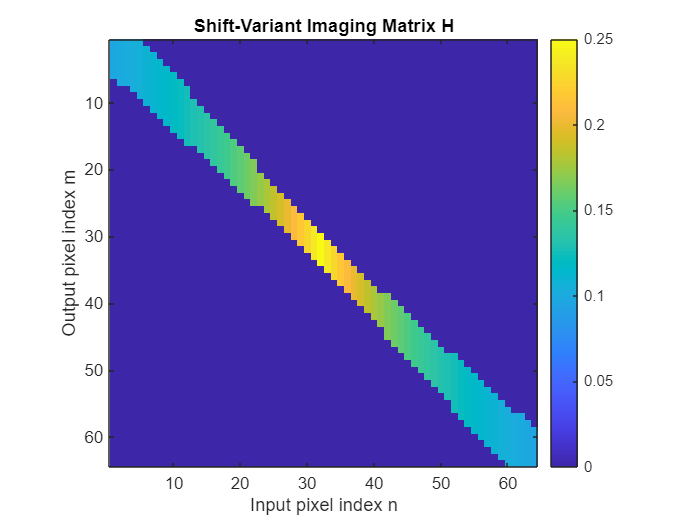

% OPTI 512R
% LAB 8
% Mohanbabu Mani


% 1.


dim    = 64;      
numpix = 5;      
beta   = 0.1;    
H = GenWeird(dim, numpix, beta);

figure;
imagesc(H);
colorbar;
title('Shift-Variant Imaging Matrix H');
xlabel('Input pixel index n');
ylabel('Output pixel index m');
axis square;

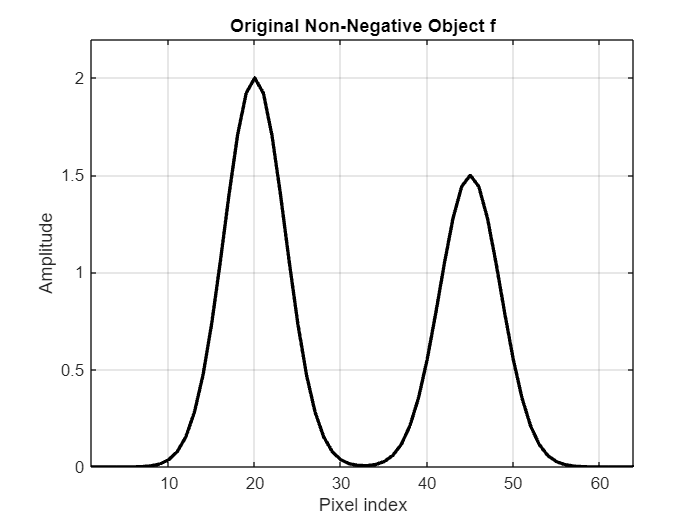


x = (1:dim)';
center1 = 20;
center2 = 45;
width   = 5;

f = 2*exp(-((x-center1)/width).^2) + 1.5*exp(-((x-center2)/width).^2);

figure;
plot(x, f, 'k-', 'LineWidth', 2);
grid on;
title('Original Non-Negative Object f');
xlabel('Pixel index');
ylabel('Amplitude');
xlim([1 dim]);
ylim([0 max(f)*1.1]);

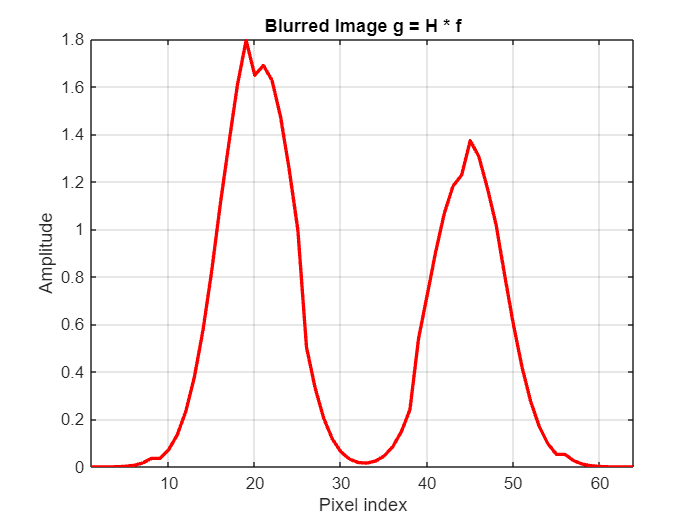


g = H * f;

figure;
plot(x, g, 'r-', 'LineWidth', 2);
grid on;
title('Blurred Image g = H * f');
xlabel('Pixel index');
ylabel('Amplitude');
xlim([1 dim]);

save('blur_experiment.mat', 'H', 'f', 'g', 'dim', 'numpix', 'beta');

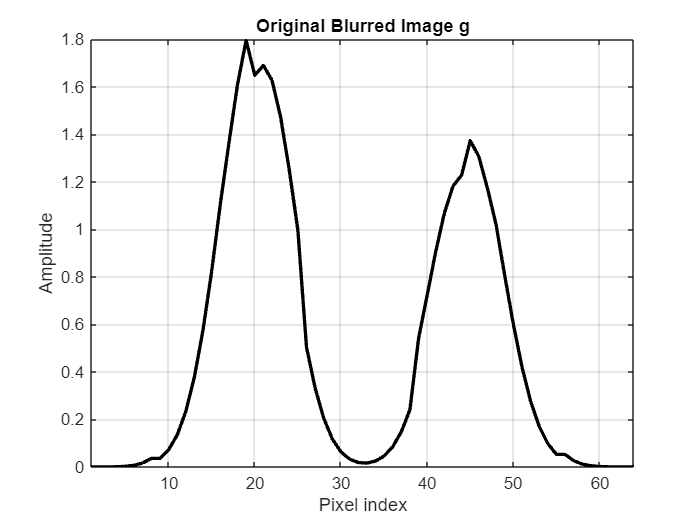

% 2.


dim    = 64;
numpix = 5;
beta   = 0.1;
H      = GenWeird(dim, numpix, beta);

x = (1:dim)';
center1 = 20;
center2 = 45;
width   = 5;
f = 2*exp(-((x-center1)/width).^2) + 1.5*exp(-((x-center2)/width).^2);
g = H * f;

figure;
plot(x, g, 'k-', 'LineWidth', 2);
grid on;
title('Original Blurred Image g');
xlabel('Pixel index');
ylabel('Amplitude');
xlim([1 dim]);

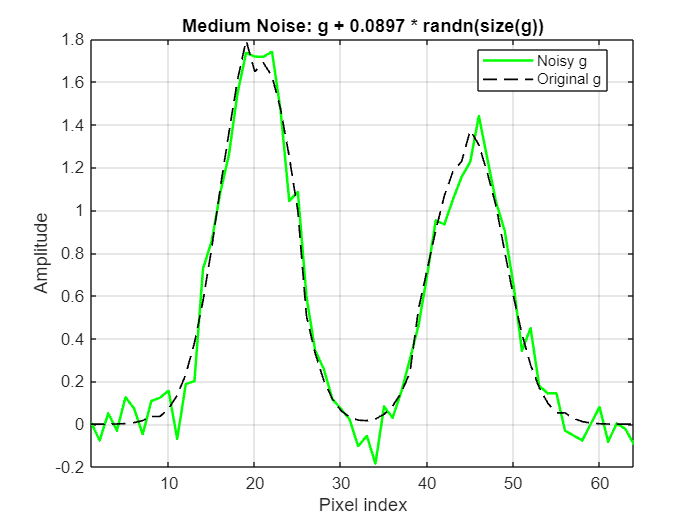


signal_range = max(g) - min(g);

s_low    = 0.02 * signal_range;  
s_medium = 0.05 * signal_range;   
s_high   = 0.15 * signal_range;   

rng(42);  

g_low    = g + s_low    * randn(size(g));
g_medium = g + s_medium * randn(size(g));
g_high   = g + s_high   * randn(size(g));

figure;
plot(x, g_low, 'b-', 'LineWidth', 1.5);
hold on;
plot(x, g, 'k--', 'LineWidth', 1);
grid on;
title(sprintf('Low Noise: g + %.4f * randn(size(g))', s_low));
xlabel('Pixel index');
ylabel('Amplitude');
legend('Noisy g', 'Original g', 'Location', 'best');
xlim([1 dim]);

figure;
plot(x, g_medium, 'g-', 'LineWidth', 1.5);
hold on;
plot(x, g, 'k--', 'LineWidth', 1);
grid on;
title(sprintf('Medium Noise: g + %.4f * randn(size(g))', s_medium));
xlabel('Pixel index');
ylabel('Amplitude');
legend('Noisy g', 'Original g', 'Location', 'best');
xlim([1 dim]);

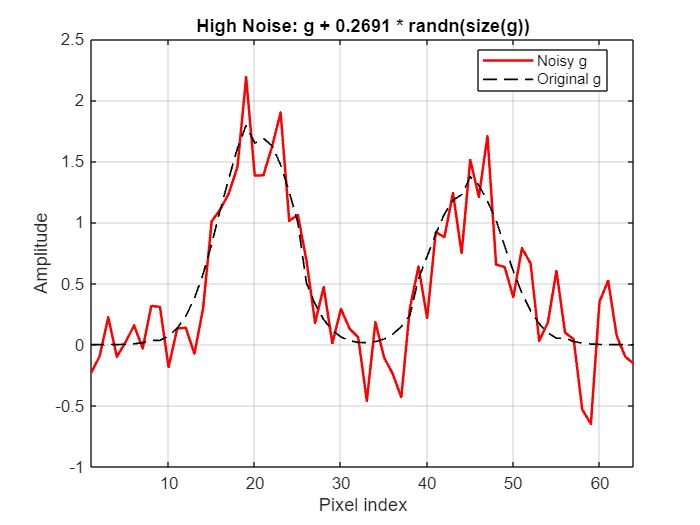


figure;
plot(x, g_high, 'r-', 'LineWidth', 1.5);
hold on;
plot(x, g, 'k--', 'LineWidth', 1);
grid on;
title(sprintf('High Noise: g + %.4f * randn(size(g))', s_high));
xlabel('Pixel index');
ylabel('Amplitude');
legend('Noisy g', 'Original g', 'Location', 'best');
xlim([1 dim]);

save('noisy_images.mat', 'g', 'g_low', 'g_medium', 'g_high', ...
     's_low', 's_medium', 's_high', 'f', 'H');

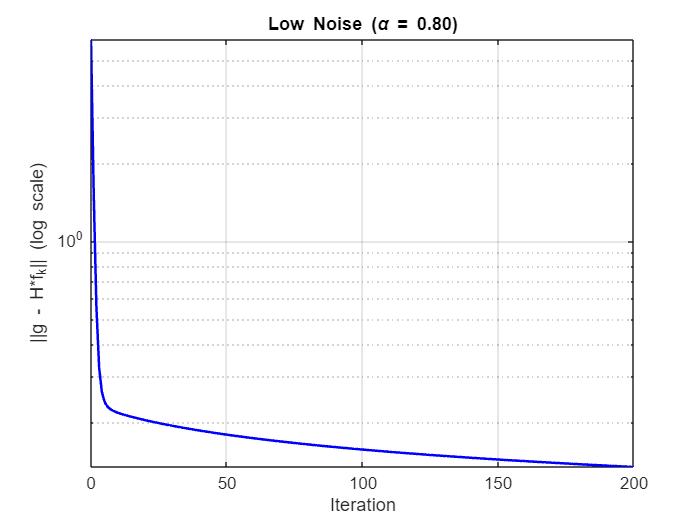

% 3.


dim    = 64;
numpix = 5;
beta   = 0.1;
H      = GenWeird(dim, numpix, beta);

x = (1:dim)';
center1 = 20;
center2 = 45;
width   = 5;
f = 2*exp(-((x-center1)/width).^2) + 1.5*exp(-((x-center2)/width).^2);
g = H * f;

signal_range = max(g) - min(g);
s_low    = 0.02 * signal_range;
s_medium = 0.05 * signal_range;
s_high   = 0.15 * signal_range;

rng(42);
g_low    = g + s_low    * randn(size(g));
g_medium = g + s_medium * randn(size(g));
g_high   = g + s_high   * randn(size(g));

max_iter = 200;

alpha_low    = 0.8;    
alpha_medium = 0.5;   
alpha_high   = 0.2;   

HtH = H' * H;

landweber = @(g_noisy, alpha, max_iter) run_landweber(H, HtH, g_noisy, alpha, max_iter);
[f_low, residuals_low] = landweber(g_low, alpha_low, max_iter);
[f_medium, residuals_medium] = landweber(g_medium, alpha_medium, max_iter);
[f_high, residuals_high] = landweber(g_high, alpha_high, max_iter);

figure;
semilogy(0:max_iter, residuals_low, 'b-', 'LineWidth', 1.5);
grid on;
title(sprintf('Low Noise (\\alpha = %.2f)', alpha_low));
xlabel('Iteration');
ylabel('||g - H*f_k|| (log scale)');

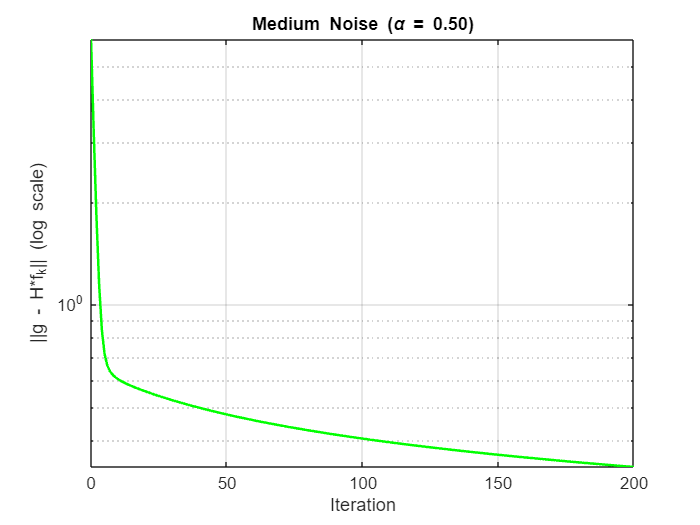


figure;
semilogy(0:max_iter, residuals_medium, 'g-', 'LineWidth', 1.5);
grid on;
title(sprintf('Medium Noise (\\alpha = %.2f)', alpha_medium));
xlabel('Iteration');
ylabel('||g - H*f_k|| (log scale)');

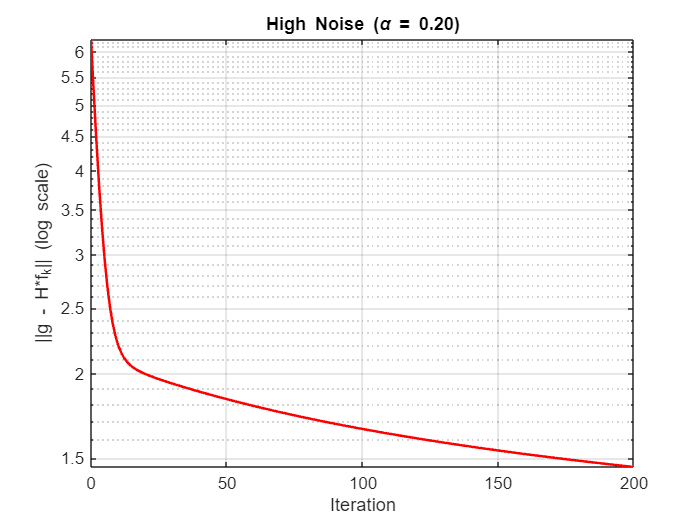


figure;
semilogy(0:max_iter, residuals_high, 'r-', 'LineWidth', 1.5);
grid on;
title(sprintf('High Noise (\\alpha = %.2f)', alpha_high));
xlabel('Iteration');
ylabel('||g - H*f_k|| (log scale)');

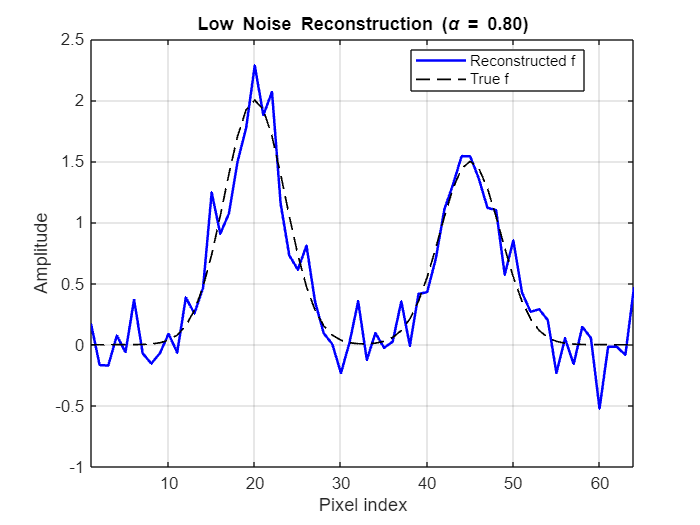


figure;
plot(x, f_low, 'b-', 'LineWidth', 1.5);
hold on;
plot(x, f, 'k--', 'LineWidth', 1);
grid on;
title(sprintf('Low Noise Reconstruction (\\alpha = %.2f)', alpha_low));
xlabel('Pixel index');
ylabel('Amplitude');
legend('Reconstructed f', 'True f', 'Location', 'best');
xlim([1 dim]);

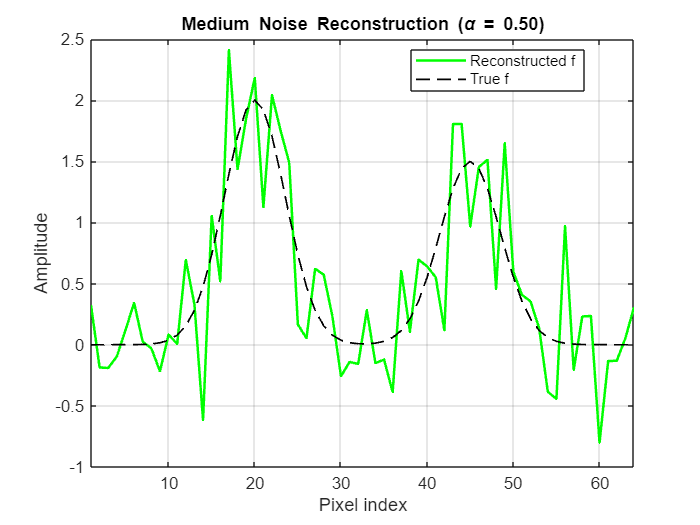


figure;
plot(x, f_medium, 'g-', 'LineWidth', 1.5);
hold on;
plot(x, f, 'k--', 'LineWidth', 1);
grid on;
title(sprintf('Medium Noise Reconstruction (\\alpha = %.2f)', alpha_medium));
xlabel('Pixel index');
ylabel('Amplitude');
legend('Reconstructed f', 'True f', 'Location', 'best');
xlim([1 dim]);

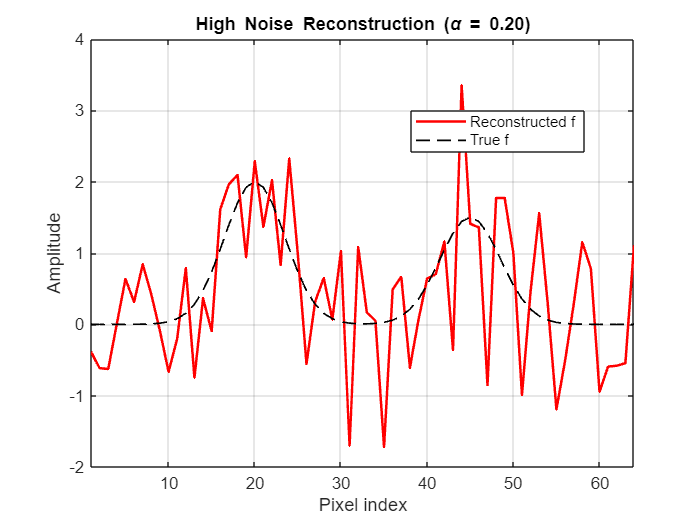


figure;
plot(x, f_high, 'r-', 'LineWidth', 1.5);
hold on;
plot(x, f, 'k--', 'LineWidth', 1);
grid on;
title(sprintf('High Noise Reconstruction (\\alpha = %.2f)', alpha_high));
xlabel('Pixel index');
ylabel('Amplitude');
legend('Reconstructed f', 'True f', 'Location', 'best');
xlim([1 dim]);



function [f_est, residuals] = run_landweber(H, HtH, g, alpha, max_iter)
    
    %   f_{k+1} = f_k + alpha * H' * (g - H * f_k)
    %          = f_k + alpha * (H'*g - H'*H*f_k)
    
    dim = size(H, 2);
    f_k = zeros(dim, 1);  
    Htg = H' * g;         
    
    residuals = zeros(max_iter+1, 1);
    residuals(1) = norm(g - H*f_k);
    
    for k = 1:max_iter
      
        gradient = Htg - HtH * f_k;
        f_k = f_k + alpha * gradient;
        
        residuals(k+1) = norm(g - H*f_k);
    end
    
    f_est = f_k;
end

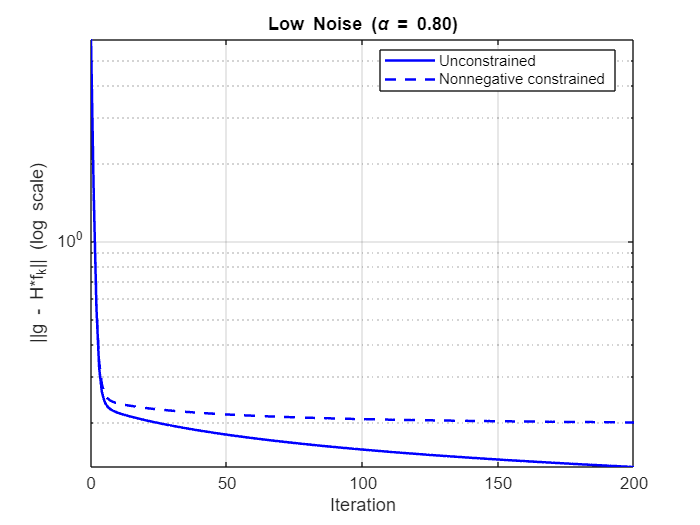

% 4.

% Low noise constraint has minimal effect.
% Medium noise constraint noticeably improves quality by eliminating negative bumps.
% High noise constraint is essential and it prevents noise driven divergence and negative artifacts.


dim    = 64;
numpix = 5;
beta   = 0.1;
H      = GenWeird(dim, numpix, beta);
x = (1:dim)';
center1 = 20;
center2 = 45;
width   = 5;
f = 2*exp(-((x-center1)/width).^2) + 1.5*exp(-((x-center2)/width).^2);
g = H * f;
signal_range = max(g) - min(g);
s_low    = 0.02 * signal_range;
s_medium = 0.05 * signal_range;
s_high   = 0.15 * signal_range;
rng(42);
g_low    = g + s_low    * randn(size(g));
g_medium = g + s_medium * randn(size(g));
g_high   = g + s_high   * randn(size(g));
max_iter = 200;
alpha_low    = 0.8;
alpha_medium = 0.5;
alpha_high   = 0.2;
HtH = H' * H;
landweber_nonneg = @(g_noisy, alpha, max_iter) ...
    run_landweber_nonneg(H, HtH, g_noisy, alpha, max_iter);


[f_low_nn, residuals_low_nn]       = landweber_nonneg(g_low, alpha_low, max_iter);
[f_medium_nn, residuals_medium_nn] = landweber_nonneg(g_medium, alpha_medium, max_iter);
[f_high_nn, residuals_high_nn]     = landweber_nonneg(g_high, alpha_high, max_iter);

[f_low_unc, residuals_low_unc]       = run_landweber(H, HtH, g_low, alpha_low, max_iter);
[f_medium_unc, residuals_medium_unc] = run_landweber(H, HtH, g_medium, alpha_medium, max_iter);
[f_high_unc, residuals_high_unc]     = run_landweber(H, HtH, g_high, alpha_high, max_iter);

figure;
semilogy(0:max_iter, residuals_low_unc, 'b-', 'LineWidth', 1.5);
hold on;
semilogy(0:max_iter, residuals_low_nn, 'b--', 'LineWidth', 1.5);
grid on;
title(sprintf('Low Noise (\\alpha = %.2f)', alpha_low));
xlabel('Iteration');
ylabel('||g - H*f_k|| (log scale)');
legend('Unconstrained', 'Nonnegative constrained', 'Location', 'best');

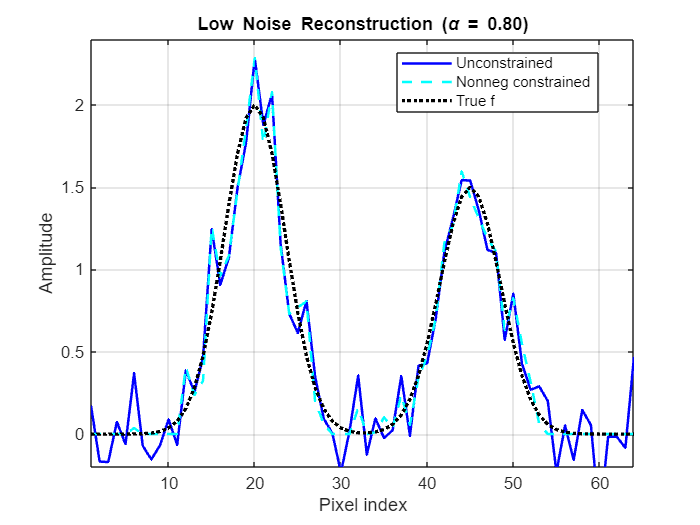


figure;
plot(x, f_low_unc, 'b-', 'LineWidth', 1.5);
hold on;
plot(x, f_low_nn, 'c--', 'LineWidth', 1.5);
plot(x, f, 'k:', 'LineWidth', 2);
grid on;
title(sprintf('Low Noise Reconstruction (\\alpha = %.2f)', alpha_low));
xlabel('Pixel index');
ylabel('Amplitude');
legend('Unconstrained', 'Nonneg constrained', 'True f', 'Location', 'best');
xlim([1 dim]);
ylim([-0.2 max(f)*1.2]);

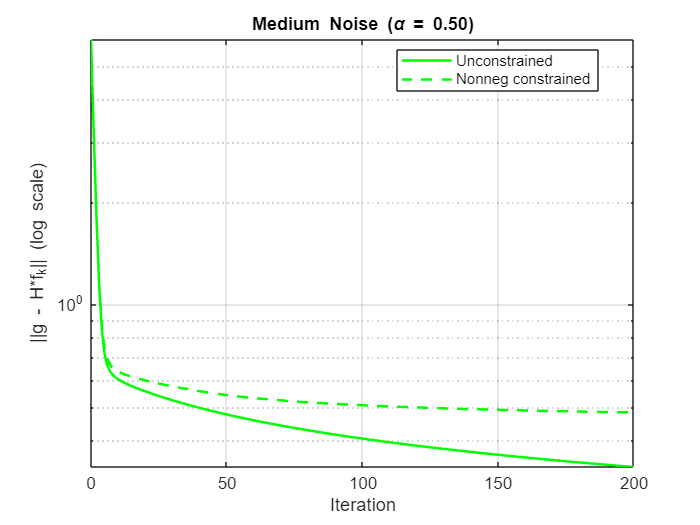


figure;
semilogy(0:max_iter, residuals_medium_unc, 'g-', 'LineWidth', 1.5);
hold on;
semilogy(0:max_iter, residuals_medium_nn, 'g--', 'LineWidth', 1.5);
grid on;
title(sprintf('Medium Noise (\\alpha = %.2f)', alpha_medium));
xlabel('Iteration');
ylabel('||g - H*f_k|| (log scale)');
legend('Unconstrained', 'Nonneg constrained', 'Location', 'best');

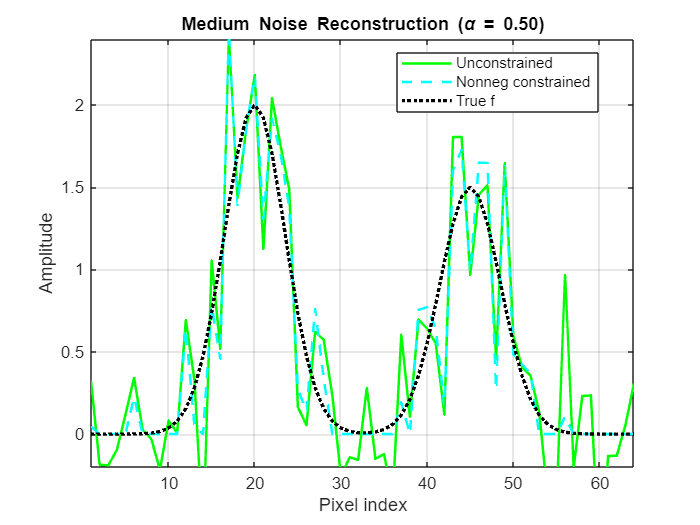


figure;
plot(x, f_medium_unc, 'g-', 'LineWidth', 1.5);
hold on;
plot(x, f_medium_nn, 'c--', 'LineWidth', 1.5);
plot(x, f, 'k:', 'LineWidth', 2);
grid on;
title(sprintf('Medium Noise Reconstruction (\\alpha = %.2f)', alpha_medium));
xlabel('Pixel index');
ylabel('Amplitude');
legend('Unconstrained', 'Nonneg constrained', 'True f', 'Location', 'best');
xlim([1 dim]);
ylim([-0.2 max(f)*1.2]);

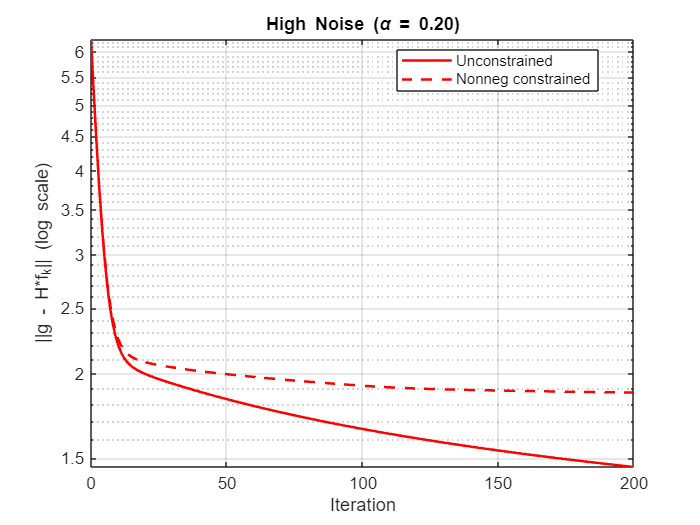


figure;
semilogy(0:max_iter, residuals_high_unc, 'r-', 'LineWidth', 1.5);
hold on;
semilogy(0:max_iter, residuals_high_nn, 'r--', 'LineWidth', 1.5);
grid on;
title(sprintf('High Noise (\\alpha = %.2f)', alpha_high));
xlabel('Iteration');
ylabel('||g - H*f_k|| (log scale)');
legend('Unconstrained', 'Nonneg constrained', 'Location', 'best');

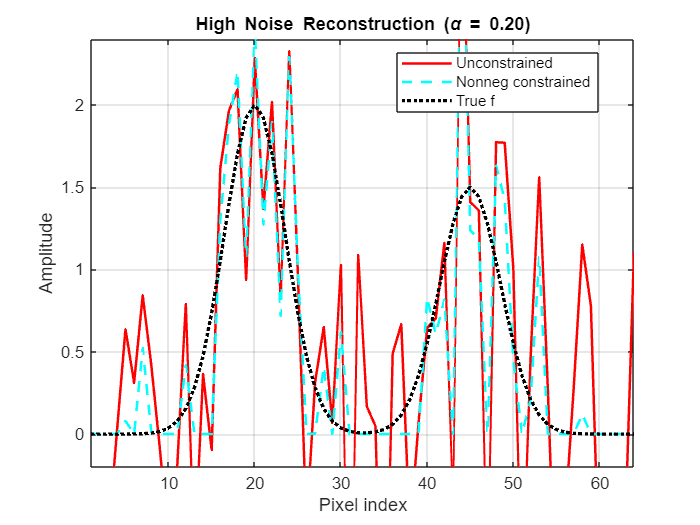


figure;
plot(x, f_high_unc, 'r-', 'LineWidth', 1.5);
hold on;
plot(x, f_high_nn, 'c--', 'LineWidth', 1.5);
plot(x, f, 'k:', 'LineWidth', 2);
grid on;
title(sprintf('High Noise Reconstruction (\\alpha = %.2f)', alpha_high));
xlabel('Pixel index');
ylabel('Amplitude');
legend('Unconstrained', 'Nonneg constrained', 'True f', 'Location', 'best');
xlim([1 dim]);
ylim([-0.2 max(f)*1.2]);



    function [f_est, residuals] = run_landweber_nonneg(H, HtH, g, alpha, max_iter)
        dim = size(H, 2);
        f_k = zeros(dim, 1);
        Htg = H' * g;
        residuals = zeros(max_iter+1, 1);
        residuals(1) = norm(g - H*f_k);
        
        for k = 1:max_iter
            gradient = Htg - HtH * f_k;
            f_k = f_k + alpha * gradient;
            f_k(f_k < 0) = 0;
            
            residuals(k+1) = norm(g - H*f_k);
        end
        
        f_est = f_k;
    end